# **各向同性的静磁幻觉装置**

**        设计静态磁性幻觉装置，可以实现对特定形状特定物体的伪装，使物体在覆盖了一个套层之后被雷达误认成另外一种物体。这项工作中所设计的电磁器件在科研、军事、国防等领域存在潜在的应用价值。  对于幻觉设备，半径为**$r=R_1$**的圆代表磁导率为**$\mu =\mu_0$**的原始物体，在原始物体上覆盖着一层半径为**$R_1 <r<R_2$**磁导率为**$\mu =\mu_2$**的幻觉套层。对于幻觉目标模型，半径为 **$R_2$**的圆代表放在材料磁导率为**$\mu =\mu_3$**背景下的磁导率为**$\mu =\mu_1$**的幻觉物体。**

**        注意，与**[**上一小节**](matlab:open('./C7_Isotropic_Static_Magnetic_Invisibility_Cloak.mlx'))**不同的是，此处的**$\mu_0$**不一定为0，即需要幻形处理的装置可以是任何物体。**

**        设两种情况下在区域 **$r>R_2$**内的磁场分布完全一样，通过对拉普拉斯方程**$\nabla^2 \phi_m =0$**进行分离变量，并匹配边界条件，计算得到**$R_1 <r<R_2$**幻觉套层区域内的磁导率分布可以表达为：**

    
$$\mu_2 =\sqrt{\mu_{2r} \mu_{2\theta } }=\frac{n\left(\mu_1 -\mu_0 \right)}{2}\pm \frac{\sqrt{n^2 {\left(\mu_1 -\mu_0 \right)}^2 +4\mu_0 \mu_1 }}{2}$$


**        其中，**$n=\frac{{\left(R_2 /R_1 \right)}^{2l} +1}{{\left(R_2 /R_1 \right)}^{2l} -1}$**,**$l=\sqrt{\frac{{\mu_{2\theta } }_{\;} }{\mu_{2r} }}$**。仿真中的参数设置为**$R_1 =5\textrm{mm}$**，**$R_2 =10\textrm{mm}$**，**$\mu_0 =2$**，**$\mu_1 =20$**。根据磁导率分布表达式计算可得套层之间**${\;R}_2 -R_1$**的磁导率为**$\mu_2 =31\ldotp 28$**。**

**       定义参数：**

**内柱半径：**

a =0.8;

**原始物体磁导率：**

u0 =4.9;

**幻觉物体磁导率：**

u1 =7.9;

**柱套层半径：**

b =1;

**计算可得柱套层的介电常数为：**

u2 = ((b/a)^2+1)/((b/a)^2-1)*(u1-u0)/2+sqrt((((b/a)^2+1)/((b/a)^2-1))^2*(u1-u0)^2+4*u0*u1)/2

u2 = 16.0748

**        用pdetool仿真：**

- **幻形目标模型的磁势分布：**

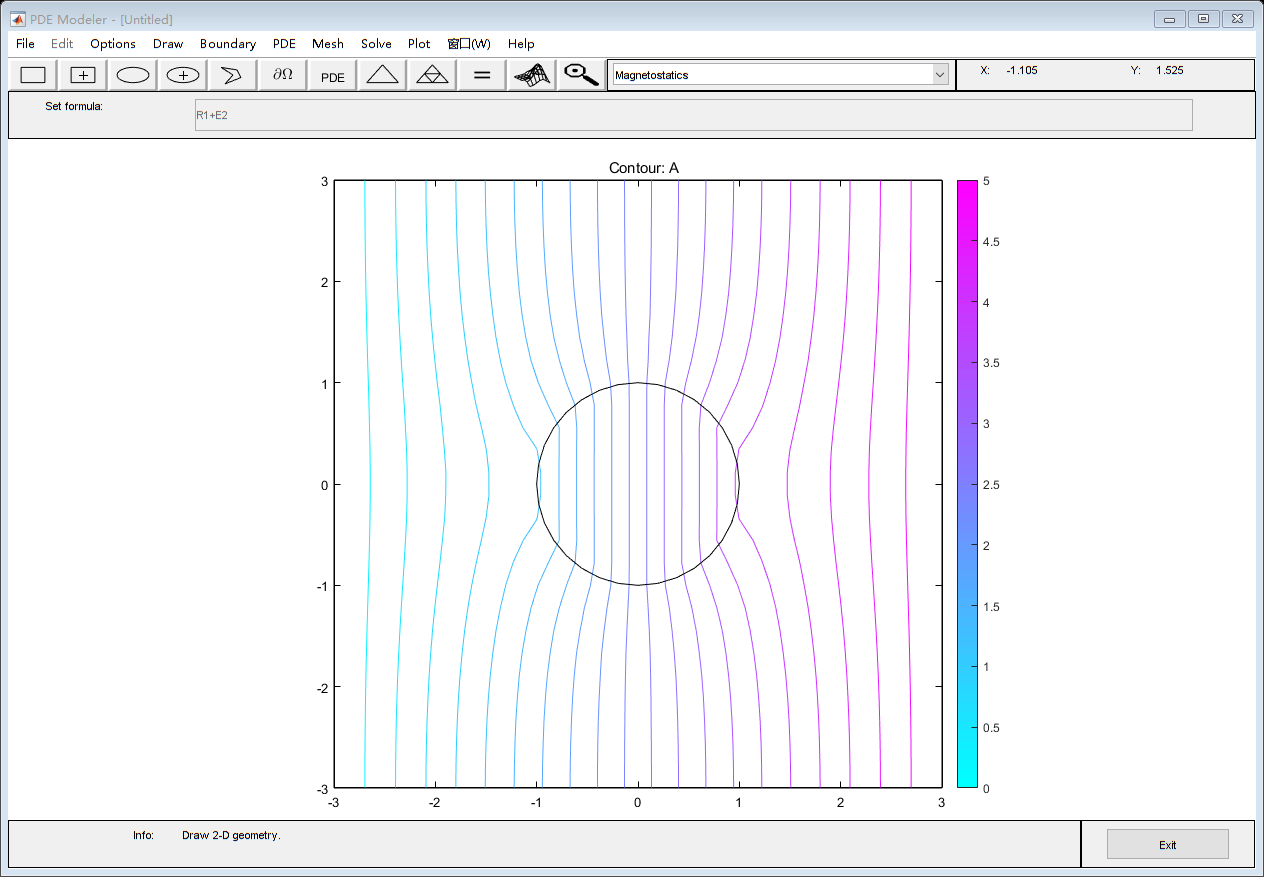

Illusion_Object_Model(a,b,u1)

- **只有原始物体时的磁势分布，此时**$\mu_2 =1$**：**

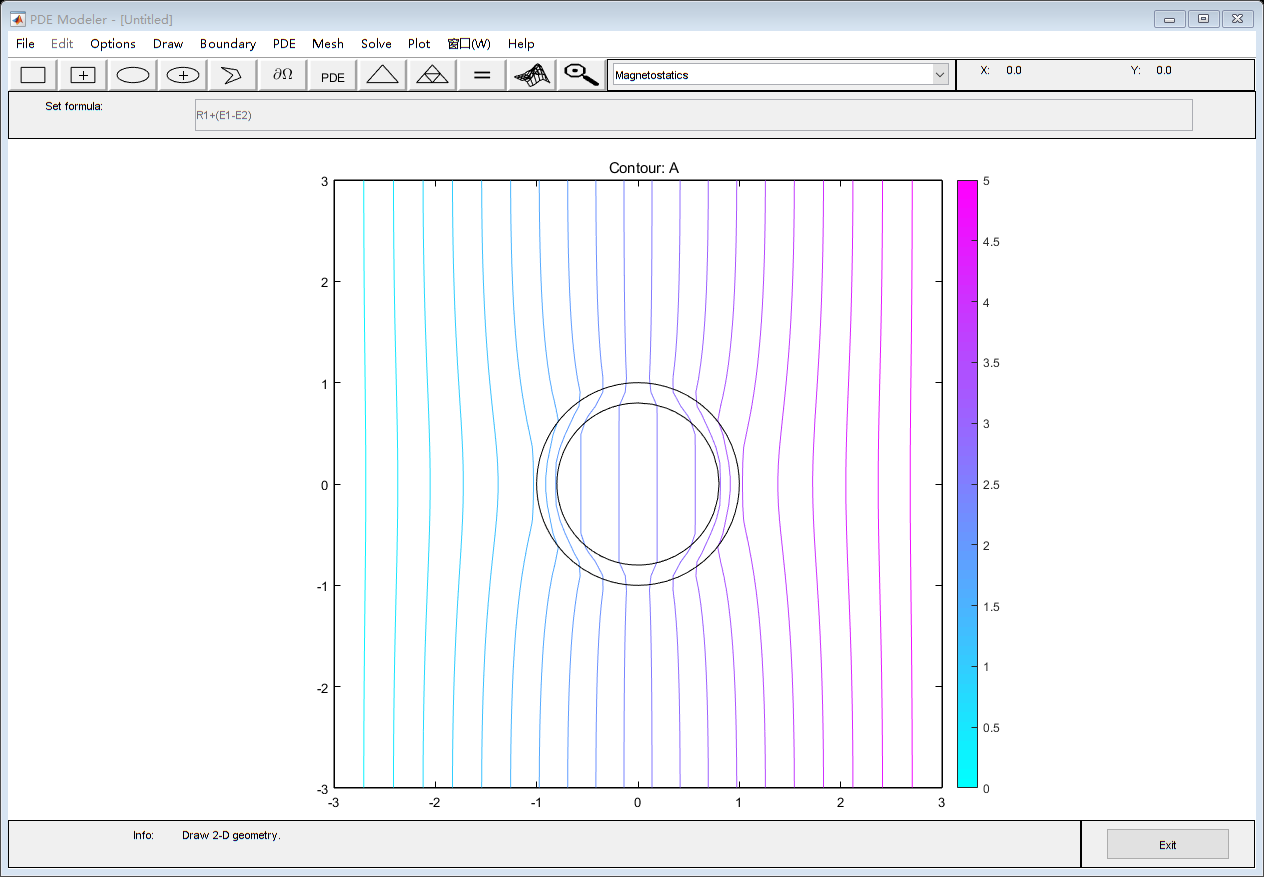

Without_Illusion_Device(a,b,u0)

- **使用幻形材料包裹圆柱体的磁势分布：**

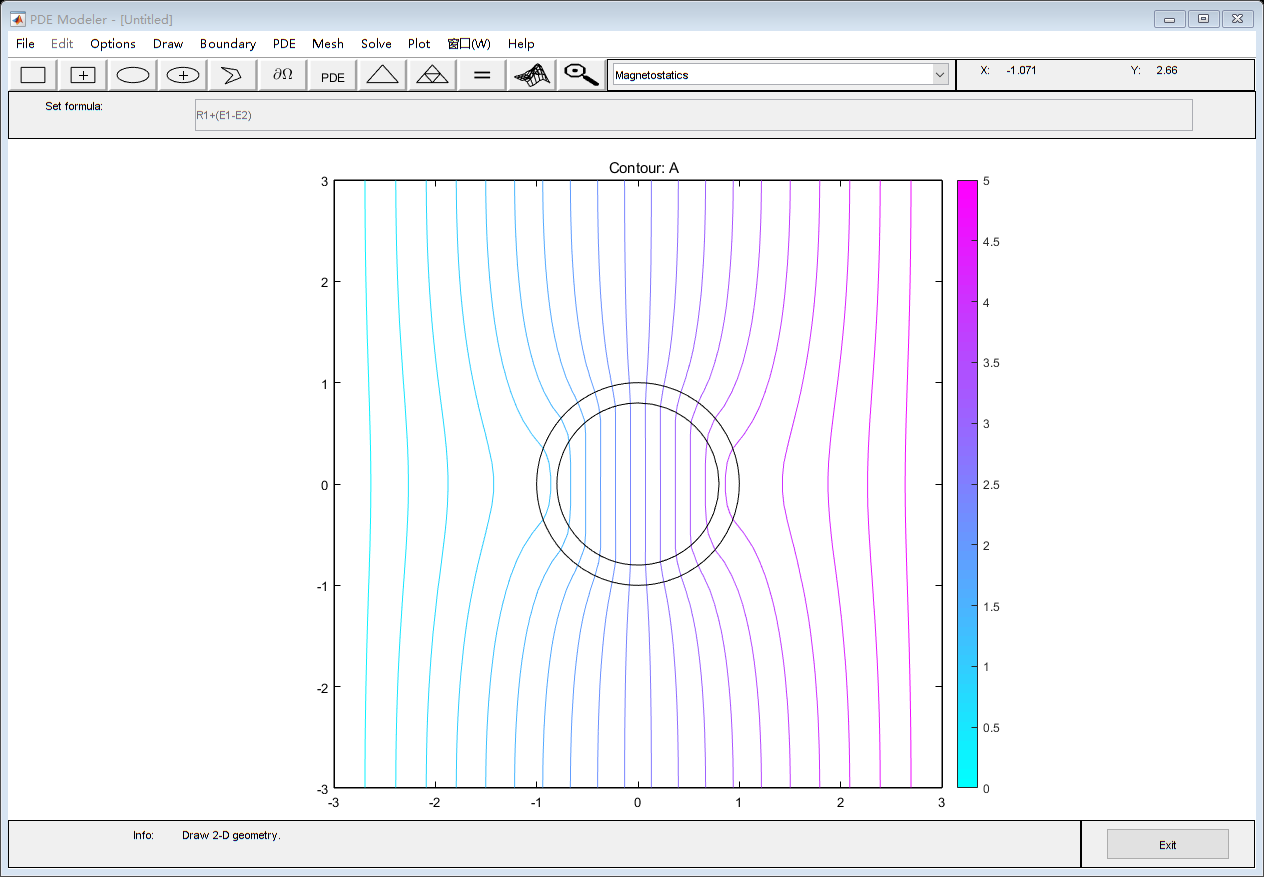

With_Illusion_Device(a,b,u0,u2)

**        由两次仿真结果可见，在原始物体上覆盖一层各向同性材料之后的磁场分布与幻觉物体的磁场分布一模一样。因此，探测器可将一个覆盖有各向同性幻觉套层材料的物体误探测为另一种物体。因此，设计结果达到了幻觉的目的。**

function Illusion_Object_Model(a,b,u1)
    u = ['1.0!', num2str(u1)];
    uu = ['1./(1.0)!1./(',num2str(u1),')'];
    current_density='0!0';
    % Make the string lengths equal
    current_density = [current_density, blanks(length(u) - length(current_density))];


    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',6);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[3 3 1]);
    set(ax,'XLimMode','auto');
    set(ax,'YLimMode','auto');
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([3 -3 3 -3],'R1');
    pdeellip(0,0,b,b,...
    0,'E2');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1+E2')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    uu,...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    [u;...
    current_density])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','1992','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 1 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end

function With_Illusion_Device(a,b,u0,u2)
    u = ['1.0!', num2str(u0),'!', num2str(u2)];
    uu = ['1./(1.0)!1./(',num2str(u0),')!1./(',num2str(u2),')'];
    current_density='0!0!0';
    % Make the string lengths equal
    current_density = [current_density, blanks(length(u) - length(current_density))];


    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',6);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[3 3 1]);
    set(ax,'XLimMode','auto');
    set(ax,'YLimMode','auto');
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pdeellip(0,0,b,b,...
    0,'E1');
    pdeellip(0,0,a,a,...
    0,'E2');
    pderect([3 -3 3 -3],'R1');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1+(E1-E2)')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    uu,...
    '0.0!0.0!0.0',...
    '0!0!0',...
    '1.0!1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    [u;...
    current_density])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','2508','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 1 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end
function Without_Illusion_Device(a,b,u0)
    u2=1;
    u = ['1.0!', num2str(u0),'!', num2str(u2)];
    uu = ['1./(1.0)!1./(',num2str(u0),')!1./(',num2str(u2),')'];
    current_density='0!0!0';
    % Make the string lengths equal
    current_density = [current_density, blanks(length(u) - length(current_density))];

    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',6);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[3 3 1]);
    set(ax,'XLimMode','auto');
    set(ax,'YLimMode','auto');
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pdeellip(0,0,b,b,...
    0,'E1');
    pdeellip(0,0,a,a,...
    0,'E2');
    pderect([3 -3 3 -3],'R1');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1+(E1-E2)')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    uu,...
    '0.0!0.0!0.0',...
    '0!0!0',...
    '1.0!1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    [u;...
    current_density])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','2508','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 1 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end

- **参考文献：**

**                [1]鲁翠. 基于人工电磁材料的多功能电磁装置及磁幻觉装置研究[D].兰州大学,2017.**